%% Setup Simulation Parameters
clc;clear;close all

%Simulation paramters
sim_time = 100; %[s]
dt = 0.1;%[s]
steps = sim_time/dt;
num_vehicles = 3;
mass_vehicle = 1500;

%Arroys to store results 
t = zeros(1,steps);
positions = zeros(num_vehicles, steps);
velocities = zeros(num_vehicles,steps);
accelerations = zeros(num_vehicles,steps);
spacings = zeros(num_vehicles-1,steps);
control_inputs = zeros(num_vehicles-1,steps);
brake_lengths=zeros(num_vehicles,steps);

%Brake Parameters
reaction_time = 0.3; % human reaction? maybe different value for other versions
friction_coef = 0.7; %dry asphalt
g = 9.81; % [m/s^2]

%init vehicles 
init_vel = 20; %[m/s]
init_spacing= 10;%[m]

vehicles = cell(1:num_vehicles);
for i=1:num_vehicles
    vehicles{i}=VehiclesDynamics(mass_vehicle, -(i-1)*init_spacing,init_vel,0);
end

%init controllers
% Create controllers for each following vehicle
controllers = cell(1, num_vehicles-1);

% Parameters for controllers
h = 1.0;                % Time headway (s)
desired_distance = 3;  % Standstill distance (m)

% Uncomment ONE set of controllers at a time to test different configurations

% Option 1: Both following vehicles use CTH Controller
controllers{1} = CTHController(h,0.9,0.1,desired_distance);
controllers{2} = CTHController(h,0.9,0.1,desired_distance);
controller_name = 'CTH';

% for j = 1:num_vehicles-1
%     controllers{j} = PIDController(h,desired_distance,0.6,0.1,0.3,dt)
% end
% controller_name= 'PID';
% Option 2: Both following vehicles use PID Controller
% controllers{1} = PIDController(h, desired_distance, 0.6, 0.1, 0.3, dt);
% controllers{2} = PIDController(h, desired_distance, 0.6, 0.1, 0.3, dt);
% controller_name = 'PID';

% Option 3: Both following vehicles use Sliding Mode Controller
% controllers{1} = SMCController(h, desired_distance, 2.0, 0.5, 0.1);
% controllers{2} = SMCController(h, desired_distance, 2.0, 0.5, 0.1);
% controller_name = 'SMC';

% Option 4: Both following vehicles use Nonlinear Controller
% controllers{1} = NonlinearController(h, desired_distance, 0.5, 0.8, 0.3, 2.0, 3.0);
% controllers{2} = NonlinearController(h, desired_distance, 0.5, 0.8, 0.3, 2.0, 3.0);
% controller_name = 'Nonlinear';

% Option 5: Mixed controllers
% controllers{1} = CTHController(h, 0.5, 0.2, desired_distance);
% controllers{2} = PIDController(h, desired_distance, 0.6, 0.1, 0.3, dt);
% controller_name = 'Mixed-CTH-PID';


for i = 1:steps 
    t(i) = (i-1)*dt;

    % Hard braking condition for the leader
    if t(i) < 25
        u1 = 0;
    else 
        u1 = -3.0;  % Hard braking
    end

    %% Update leader vehicle
    vehicles{1}.update(u1);

    % Store leader's information
    positions(1,i) = vehicles{1}.position;
    velocities(1,i) = vehicles{1}.velocity;
    accelerations(1,i) = vehicles{1}.acceleration;

    % Check if the leader has stopped completely
    if velocities(1,i) <= 0 && vehicles{1}.acceleration == 0
        % Stop the leader after braking
        vehicles{1}.velocity = 0;
        vehicles{1}.acceleration = 0;
        u1 = 0; % No more control input, the vehicle stays stopped
        % Ensure the leader's position does not update after stopping
        positions(1,i:end) = vehicles{1}.position;
    end

    % Brake length = reaction distance + brake distance
    v1 = max(0, velocities(1,i)); 
    reaction_distance = v1 * reaction_time;
    brake_distance = (v1^2) / (2 * friction_coef * g);
    brake_lengths(1,i) = reaction_distance + brake_distance;

    %% Update following vehicles
    for n = 2:num_vehicles
        %% Index for following vehicles
        prev_idx = n - 1;
        ctrl_idx = n - 1;
        u = controllers{ctrl_idx}.calculate_control(vehicles{n}.position, ...
                vehicles{n}.velocity, vehicles{n}.acceleration, vehicles{prev_idx}.position, ...
                vehicles{prev_idx}.velocity, vehicles{prev_idx}.acceleration);

        control_inputs(n - 1, i) = u;
        vehicles{n}.update(u);

        positions(n, i) = vehicles{n}.position;
        velocities(n, i) = vehicles{n}.velocity;
        accelerations(n, i) = vehicles{n}.acceleration;
        spacings(n - 1, i) = vehicles{prev_idx}.position - vehicles{n}.position;

        % Brake length calculation for following vehicles
        v_current = max(0, velocities(n, i));
        reaction_distance = v_current * reaction_time;
        braking_distance = (v_current^2) / (2 * friction_coef * g);
        brake_lengths(n, i) = reaction_distance + braking_distance;
    end
end

%% Calculate the String Stability metrics
%% Spacing error
spacing_errors = zeros(num_vehicles - 1, steps);

for i = 2:num_vehicles
    spacing_errors(i - 1, :) = spacings(i - 1, :) - (desired_distance + h * velocities(i, :));
end

brake_phase = t >= 5 & t <= 15;
max_errors = max(abs(spacing_errors(:, brake_phase)), [], 2);
error_ampl = max_errors(end) / max_errors(1); % Maximum amplification
string_stable = error_ampl <= 1.0;

acc_phase = t >= 5 & t <= 15;
max_acc = max(abs(accelerations(:, acc_phase)), [], 2);
acc_ampl = max_acc(2:end) ./ max_acc(1:end - 1);

brake_length_diffs = diff(brake_lengths, 1, 1);
safety_margins = spacings - brake_length_diffs;
min_safety_Margins = min(safety_margins(:, brake_phase), [], 2);
brake_length_margin = min(min_safety_Margins);



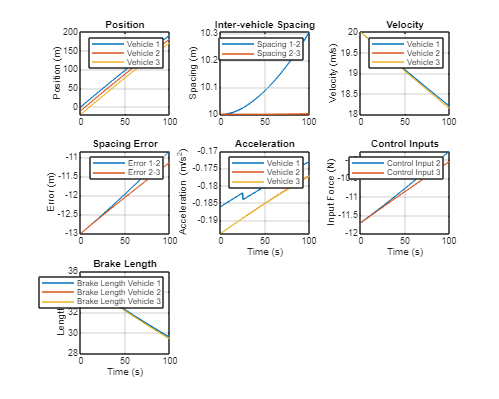

%% Plot Results
figure('Name', ['Brake Scenario Simulation - ' controller_name], 'Position', [100, 100, 1000, 800]);

subplot(3, 3, 1);
plot(t, positions);
legend(arrayfun(@(x) sprintf('Vehicle %d', x), 1:num_vehicles, 'UniformOutput', false));
title('Position');
ylabel('Position (m)');
grid on;

subplot(3, 3, 3);
plot(t, velocities);
legend(arrayfun(@(x) sprintf('Vehicle %d', x), 1:num_vehicles, 'UniformOutput', false));
title('Velocity');
ylabel('Velocity (m/s)');
grid on;

subplot(3, 3, 5);
plot(t, accelerations);
legend(arrayfun(@(x) sprintf('Vehicle %d', x), 1:num_vehicles, 'UniformOutput', false));
title('Acceleration');
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');
grid on;

subplot(3, 3, 2);
plot(t, spacings);
hold on;
legend(arrayfun(@(x) sprintf('Spacing %d-%d', x, x+1), 1:num_vehicles-1, 'UniformOutput', false));
title('Inter-vehicle Spacing');
ylabel('Spacing (m)');
grid on;

subplot(3, 3, 4);
plot(t, spacing_errors);
legend(arrayfun(@(x) sprintf('Error %d-%d', x, x+1), 1:num_vehicles-1, 'UniformOutput', false));
title('Spacing Error');
ylabel('Error (m)');
grid on;

subplot(3, 3, 6);
plot(t, control_inputs);
legend(arrayfun(@(x) sprintf('Control Input %d', x+1), 1:num_vehicles-1, 'UniformOutput', false));
title('Control Inputs');
xlabel('Time (s)');
ylabel('Input Force (N)');
grid on;

subplot(3, 3, 7);
plot(t, brake_lengths);
legend(arrayfun(@(x) sprintf('Brake Length Vehicle %d', x), 1:num_vehicles, 'UniformOutput', false));
title('Brake Length');
xlabel('Time (s)');
ylabel('Length (m)');
grid on